## Load the data 

The provided data set, “CIFAR2_data.mat” is a subset of the CIFAR-10 dataset. It consists of 10,000 32x32 color images in 2 classes {“vehicle,”horse”}. The file “CIFAR2_data.mat” contains 10,000 32x32 color images. The 32 by 32 color image is flattened into a 1 by 3071 row vector. Each of these color images becomes a single row in the data. 

clear all; clc; close all;

load('CIFAR2_data.mat');  


## 1. Split the data into training and testing sets with an 80-20 split. 

You can use the function ““mySplitData.m” developed in Lab3.  

%Task1: Splits the data into 80% training and 20% testing
[XTrain, XTest, yTrain, yTest] = mySplitData(data, label , 0.8);
whos

  Name            Size                 Bytes  Class     Attributes

  XTest        2000x3072             6144000  uint8               
  XTrain       8000x3072            24576000  uint8               
  data        10000x3072            30720000  uint8               
  label       10000x1                  10000  uint8               
  yTest        2000x1                  16000  double              
  yTrain       8000x1                  64000  double              



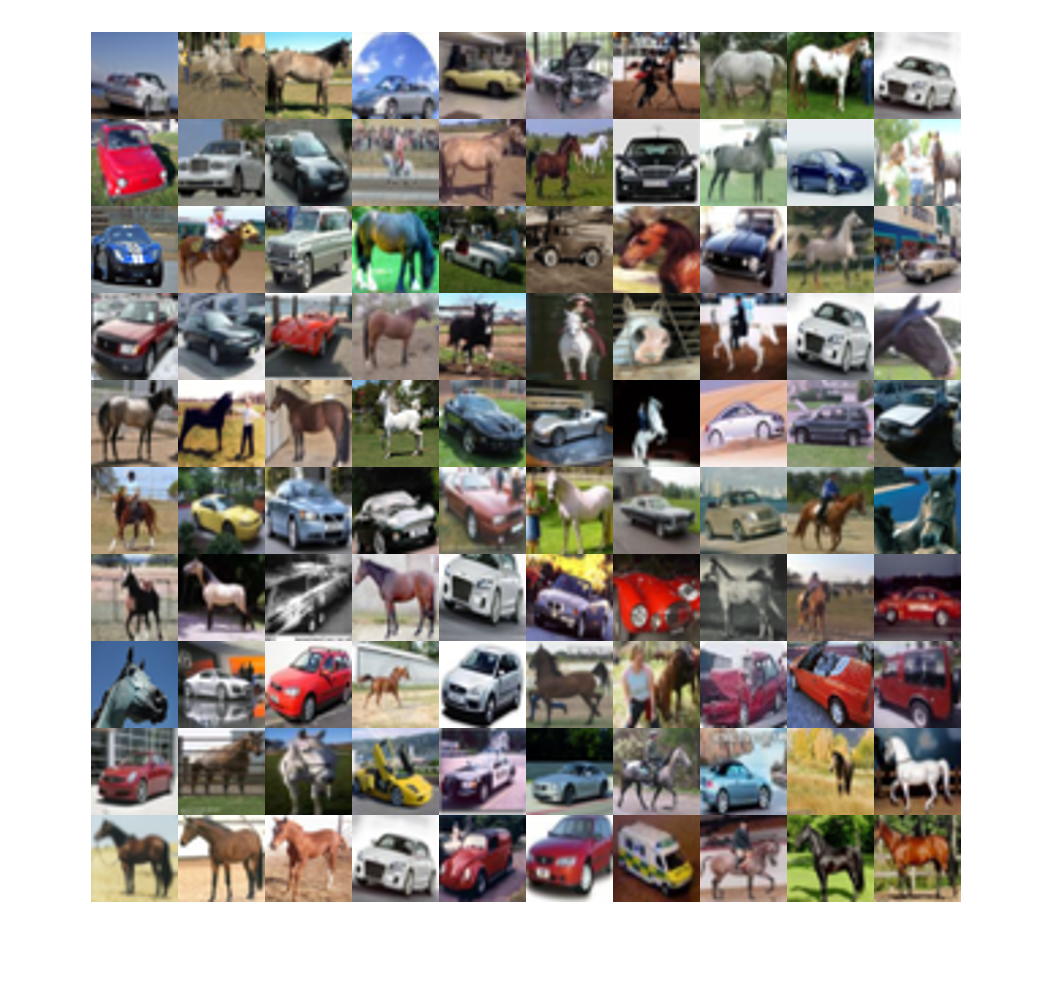


% Randomly select 100 data points from the training data to display
%numSample is the number of samples,  XTrain is the training input data
[numSample, numFeatures] = size(XTrain);
rand_indices = randperm(numSample,100);  %returns a row vector containing a random permutation of the integers from 1 to n inclusive.
image_sel = XTrain(rand_indices, :);
displayData(image_sel); 

## 2. Data Preprocessing: 

1)Data normalization

- In machine learning, data normalization is a procedure that **m****akes input features are in the similar ranges. **Another reason why the data normalization is applied is that gradient descent converges much faster with feature scaling than without feature scaling. 

- Do the data normalization in the range of [0,1]  using the Min-Max method. The equation of the Min_Max methos is given below:

                                       
$$\mathit{\mathbf{n}}\mathit{\mathbf{o}}\mathit{\mathbf{r}}{\mathit{\mathbf{m}}}_{\mathit{\mathbf{x}}} =\frac{\mathit{\mathbf{x}}-\min {\left(\mathit{\mathbf{x}}\right)}}{\max {\left(\mathit{\mathbf{x}}\right)}\mathit{\mathbf{ }}-\mathit{\mathbf{m}}\mathit{\mathbf{i}}\mathit{\mathbf{n}}\left(\mathit{\mathbf{x}}\right)}$$
                                 

**          , **where x is a column vector,  min(x) is the minimum of the column vector x , and max(x) is the maximum  of the column vector x.

2) Y data preparation

We need to generate 2 out nodes in the output layer.     y=${\left[\begin{array}{c}
\begin{array}{c}
y_1 \\
y_2 
\end{array}\\

\end{array}\right]}$                           

The label ‘1’= ${\left[\begin{array}{c}
\begin{array}{c}
1\\
0
\end{array}\\

\end{array}\right]}$, and the label ‘2’ =${\left[\begin{array}{c}
\begin{array}{c}
0\\
1
\end{array}\\

\end{array}\right]}$

%Task2-1:do the data normalization using the Min-Max method. 
% Do the data normalization on the training data
minv = zeros(1, size(XTrain,2));
maxv = zeros(1, size(XTrain,2));
norm_XTrain = zeros(size(XTrain));
for i = 1:numFeatures
    minv(i) = min(XTrain(:,i));
    maxv(i) = max(XTrain(:,i));
    norm_XTrain(:,i) = (double(XTrain(:,i)) - minv(i))/(maxv(i)-minv(i));
end



%Task2-2:do the data normalization on the test data using the Min-Max method. 
% Note!!!! - you need to use the columnwise min and max values generated from the training data ( statistics are from the trining data). 
norm_XTest = zeros(size(XTest));
for i = 1:numFeatures
    norm_XTest(:,i) = (double(XTest(:,i)) - minv(i))/(maxv(i)-minv(i));
end





%Task2-3:Do the Y training data conversion. Convert the y training data label data appropriately to correspond two output nodes in the output layer
% 1 =>[ 1 0], 2=>[0 1]
numLabel = length(unique(yTrain)); 
tmpY1 = repmat([1:numLabel], numSample, 1);
% repmat(y, 1, num_labels) => repeat y vector numLabel times
tmpY2 = repmat(yTrain, 1, numLabel);
% try to make 3 output y labels for NN training
% 1 => [1 0 0], 2=>[0 1 0], 3 =>[0 0 1]
y_Train = (tmpY1 == tmpY2);





%Task2-4:Do the Y test data conversion. Convert the y test data label data appropriately to correspond two output nodes in the output layer
% 1 =>[ 1 0], 2=>[0 1]
[numSample_Test, numFeatures_Test] = size(XTest);
numLabel_Test = length(unique(yTest)); 
tempY1 = repmat([1:numLabel_Test], numSample_Test, 1);
% repmat(y, 1, num_labels) => repeat y vector numLabel times
tempY2 = repmat(yTest, 1, numLabel_Test);
% try to make 3 output y labels for NN training
% 1 => [1 0 0], 2=>[0 1 0], 3 =>[0 0 1]
y_Test = (tempY1 == tempY2);






**3) Build NNs architecture using the Neural Network Pattern Recognition App**

**Task3**: Generate the script from NPRTOOL and edit the script to customize the NN training

Rather than writing code from scratch, you will utilize the **Neural Network Pattern Recognition tool (**NPRTOOL) to generate scripts from NPRTOOL GUIs, and then modify them to customize the network training. 

If needed, open the Neural Network Start GUI with this command:`nnstart`

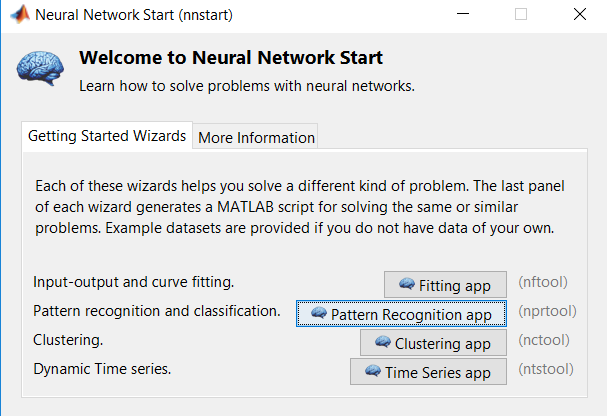

Select Pattern recognition app and train the nn as you did  in the Lab5 -part2.

%Task3: train the NN using the Neural network Pattern Recognition App as you learned in lab5-Part2.
% It is Ok the performance of the training is not good. 
%Cope and paste code generated by NPRTOOL here 

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 27-Aug-2018 23:14:31
%
% This script assumes these variables are defined:
%
%   norm_XTrain - input data.
%   y_Train - target data.

x = norm_XTrain';
t = y_Train';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
%trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.


%Code for Task4
%Task4:  Build a neural network with 5 hidden layers by modifying code generated by NPRTOOL. 
% You need to design the number of hidden nodes in each hidden layer.
% Do Task 4 by modifying the code generated by NPRTOOL.

% Create a Pattern Recognition Network
%hiddenLayerSize = 1000;
h1_Size = 1000;
h2_Size = 500;
h3_Size = 100;
h4_Size = 50;
h5_Size = 20;
Five_hidden_layers = [h1_Size h2_Size h3_Size h4_Size h5_Size];
net = patternnet(Five_hidden_layers);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 90/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 0/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
%e = gsubtract(t,y);
Performance_Train_5HiddenLayers = perform(net,t,y);
fprintf("5 hidden layer performance (Train): %d", Performance_Train_5HiddenLayers);

5 hidden layer performance (Train): 4.117144e-02

tind = vec2ind(t);
yind = vec2ind(y);
PercentErrors_Train_5HiddenLayers = sum(tind ~= yind)/numel(tind);
fprintf('Training Error (5 Hidden Layers): %d', PercentErrors_Train_5HiddenLayers);

Training Error (5 Hidden Layers): 2.225000e-02



x = norm_XTest';
t = y_Test';

y = net(x);
%e = gsubtract(t,y);
Performance_Test_5HiddenLayers = perform(net,t,y);
fprintf(" 5 hidden layer performance (Test): %d", Performance_Test_5HiddenLayers);

 5 hidden layer performance (Test): 1.115084e-01

tind = vec2ind(t);
yind = vec2ind(y);
PercentErrors_Test_5HiddenLayers = sum(tind ~= yind)/numel(tind);
fprintf("Test Error (5 Hidden Layers): %d", PercentErrors_Test_5HiddenLayers);

Test Error (5 Hidden Layers): 9.050000e-02

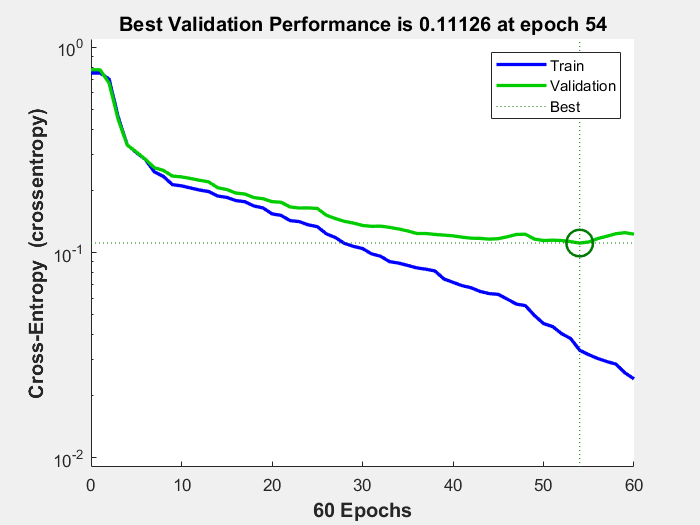

% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)

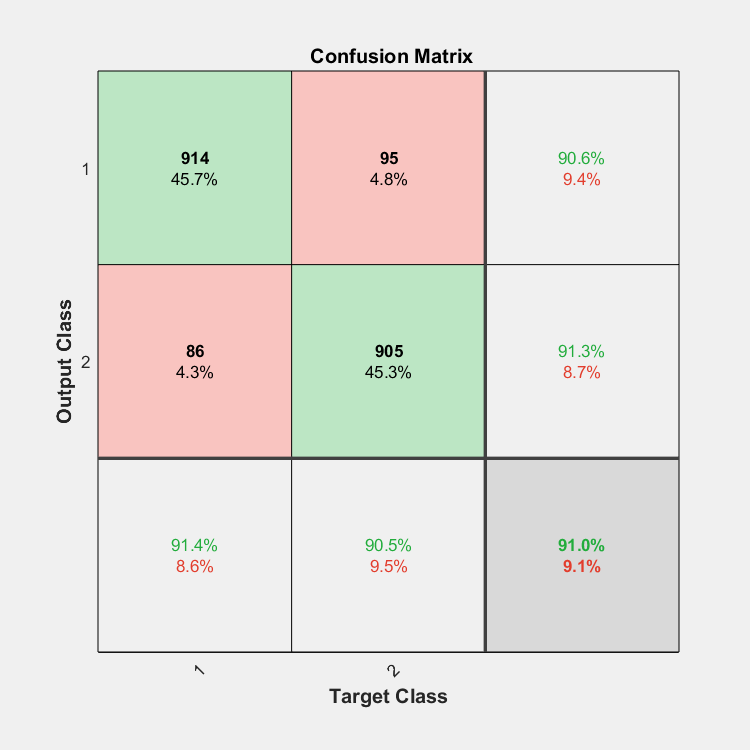

%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)

%figure, plotroc(t,y)




%Code for Task5
%Task5:Build a neural network with 3 hidden layers by modifying code generated by NPRTOOL.
% You need to design the number of hidden nodes in each hidden layer.
%Do Task 5 by modifying the code generated by NPRTOOL
x = norm_XTrain';
t = y_Train';

h1_Size = 1000;
h2_Size = 500;
h3_Size = 100;

Three_hidden_layers = [h1_Size h2_Size h3_Size];
net = patternnet(Three_hidden_layers);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 90/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 0/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
%e = gsubtract(t,y);
Performance_Train_3HiddenLayers = perform(net,t,y);
fprintf("3 hidden layer performance (Train): %d", Performance_Train_3HiddenLayers);

3 hidden layer performance (Train): 3.601619e-02

tind = vec2ind(t);
yind = vec2ind(y);
PercentErrors_Train_3HiddenLayers = sum(tind ~= yind)/numel(tind);
fprintf('Training Error (3 Hidden Layers): %d', PercentErrors_Train_3HiddenLayers);

Training Error (3 Hidden Layers): 1.987500e-02

x = norm_XTest';
t = y_Test';

y = net(x);
%e = gsubtract(t,y);

Performance_Test_3HiddenLayers = perform(net,t,y);
fprintf("3 hidden layer performance (Test): %d", Performance_Test_3HiddenLayers);

3 hidden layer performance (Test): 1.071544e-01

tind = vec2ind(t);
yind = vec2ind(y);
PercentErrors_Test_3HiddenLayers = sum(tind ~= yind)/numel(tind);
fprintf("Test Error (3 Hidden Layers): %d", PercentErrors_Test_3HiddenLayers);

Test Error (3 Hidden Layers): 7.800000e-02

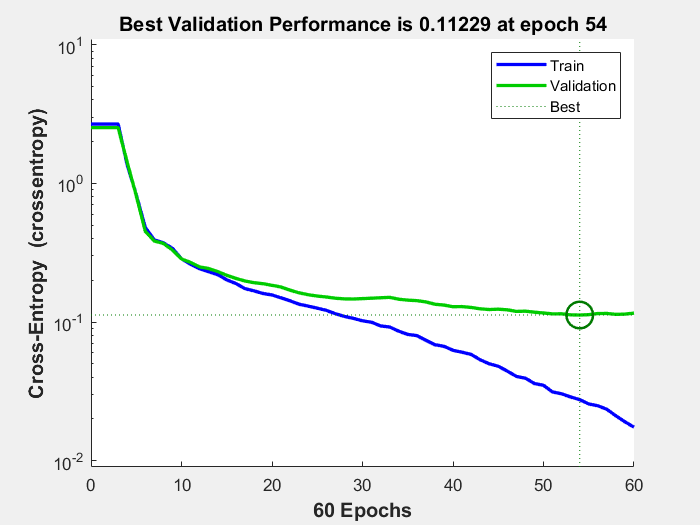

% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)

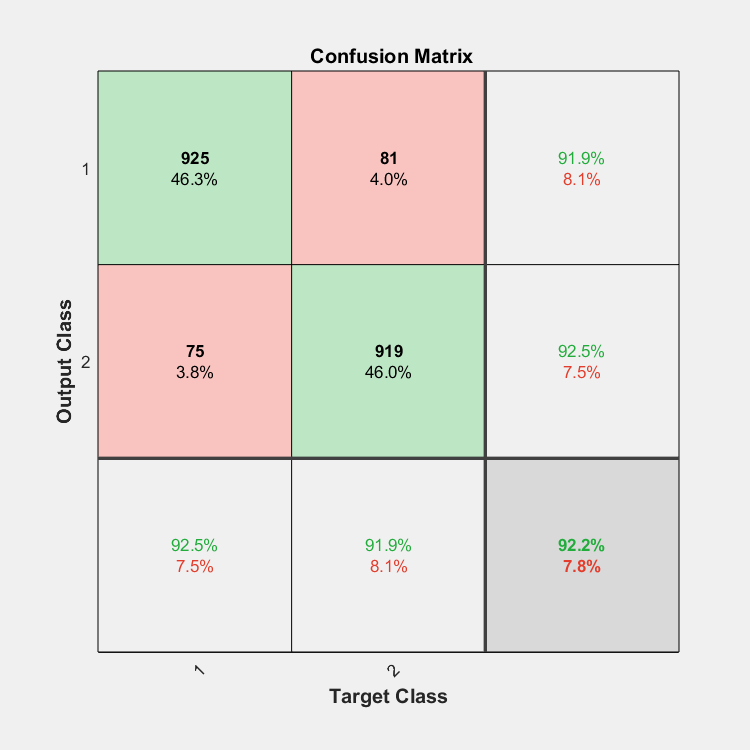

%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)

%figure, plotroc(t,y)




